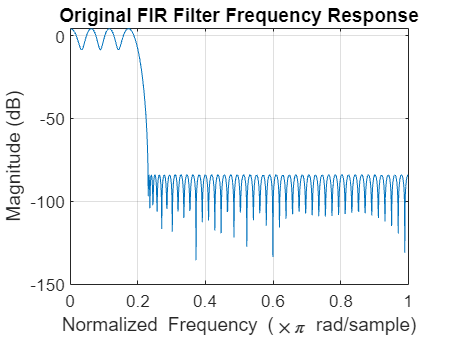

clc; 
clear; 

% Specifications
N = 100;  % Filter order
fs = 1;  % Normalized sampling frequency
wp = 0.2 * pi;  % Passband edge (rad/sample)
ws = 0.23 * pi; % Stopband edge (rad/sample)
Rs = 80;   % Stopband attenuation (dB)

% Frequency Bands Definition
% Normalized to Nyquist frequency (pi rad/sample)
f = [0 wp/pi ws/pi 1];  % Frequency bands
a = [1 1 0 0];          % Desired response
dev = [1 10^(Rs/20)];  

% FIR filter using Parks-McClellan Algorithm
b_unquant = firpm(N, f, a, dev);  

% Frequency Response of the Unquantized Filter
[H, w] = freqz(b_unquant, 1, 1024);

figure;
plot(w/pi, 20*log10(abs(H)));
grid on;
title('Original FIR Filter Frequency Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');

## Quantization

% Quantize coefficients to 32-bit (Q31)
b_Q31_int = int32(round(b_unquant * 2^32));
b_quant   = double(b_Q31_int) / 2^32;
% Check difference
coeff_error = b_unquant - b_quant;
max_coeff_err = max(abs(coeff_error));
disp(['Max coefficient error: ' num2str(max_coeff_err)]);

Max coefficient error: 1.1578e-10


## Frequency Response

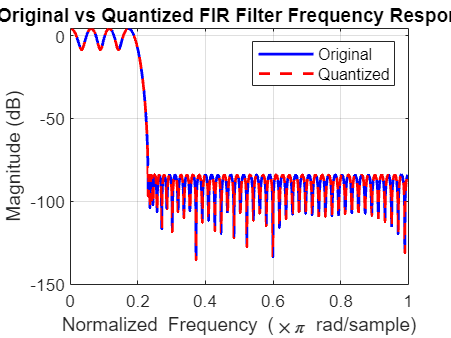

% Frequency Response of the Quantized Filter
[Hq, wq] = freqz(b_quant, 1, 1024);

figure;
plot(w/pi, 20*log10(abs(H)), 'b', 'LineWidth', 1.5); hold on;
plot(w/pi, 20*log10(abs(Hq)), 'r--', 'LineWidth', 1.5);
grid on;
title('Original vs Quantized FIR Filter Frequency Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
legend('Original', 'Quantized');


% detect Overflow
max_coeff = max(abs(b_quant));
if max_coeff > 1
    warning('Overflow, Scaling down coefficients.');
    b_quant = b_quant / max_coeff; % Scale down to prevent overflow
end


% passband ripple
passband_indices = w/pi <= 0.2; 
passband_mag = abs(H(passband_indices)); 
ripple_db = 20*log10(max(passband_mag)) - 20*log10(min(passband_mag));

fprintf('Passband Ripple: %.4f dB\n', ripple_db);

Passband Ripple: 12.7778 dB


## Quantization - Compared with original

N_samples = 90;
% 1. Create a Test Signal (Double)
Fs  = 1.0; % normalized sample rate
n   = 0:N_samples-1; 
x_d = 0.5*sin(2*pi*0.05*n) + 0.25*sin(2*pi*0.15*n);

% 2. Pass x_d through the Unquantized(oroginal) filter (Double precision)
y_d = filter(b_unquant, 1, x_d);

% 3. Quantize x_d to 32-bit (Q31), filter in 32-bit integer domain
x_Q31_int = int32(round(x_d * 2^31));

% 4. Filter with our 32-bit integer FIR routine:
y_filter_32bit_int = fir_filter_32bit(x_Q31_int, b_Q31_int);


## Output quantized coefficients and test case vectors

These are the values we put into the hardware and expect to see

fileID = fopen('.\simulation\coeffs.txt', 'w');

% Write data in integer format
fprintf(fileID, '%d\n', b_Q31_int');

% Close the file
fclose(fileID);
disp('File written successfully: coeffs.txt');

File written successfully: coeffs.txt



fileID = fopen('.\simulation\testvector.txt', 'w');

for i = 1:N_samples
    fprintf(fileID, '%d %d\n', x_Q31_int(i), y_filter_32bit_int(i));
end

fclose(fileID);
disp('File written successfully: testvector.txt');

File written successfully: testvector.txt
